clear;
%% Load Data
folder_path_healthy = 'F:\University of Maryland\Graduate School Reliability Engineering\ENME 691\Project1\Training\Healthy';
folder_path_unbalance1 = 'F:\University of Maryland\Graduate School Reliability Engineering\ENME 691\Homework\HW3\Training\Faulty\Unbalance 1';
folder_path_unbalance2 = 'F:\University of Maryland\Graduate School Reliability Engineering\ENME 691\Homework\HW3\Training\Faulty\Unbalance 2';
folder_path_testing = 'F:\University of Maryland\Graduate School Reliability Engineering\ENME 691\Project1\Testing\Testing';

all_data_healthy = loadDataFromFolder(folder_path_healthy);
all_data_unbalance1 = loadDataFromFolder(folder_path_unbalance1);
all_data_unbalance2 = loadDataFromFolder(folder_path_unbalance2);

%% Extract Harmonic Features
features_healthy = extractFeatures(all_data_healthy);
features_unbalance1 = extractFeatures(all_data_unbalance1);
features_unbalance2 = extractFeatures(all_data_unbalance2);

% Combine features and labels
X = [features_healthy; features_unbalance1; features_unbalance2];
labels = [repmat({'H'}, size(features_healthy, 1), 1); 
          repmat({'U1'}, size(features_unbalance1, 1), 1);
          repmat({'U2'}, size(features_unbalance2, 1), 1)];

%% Prepare SOM data structure
sD = som_data_struct(X, 'name', 'Machine Condition Data', 'comp_names', {'First Harmonic', 'Second Harmonic', 'Third Harmonic'});
sD = som_label(sD, 'add', 1:length(labels), labels);

%% Train SOM Model
sMap = som_make(sD);

Determining map size...
 map size [7, 6]
Initialization...
Training using batch algorithm...
Rough training phase...
Training:   0/   0 s
Finetuning phase...
Training:   0/   0 s
Final quantization error: 0.000
Final topographic error:  0.333
Final combined error:  0.000


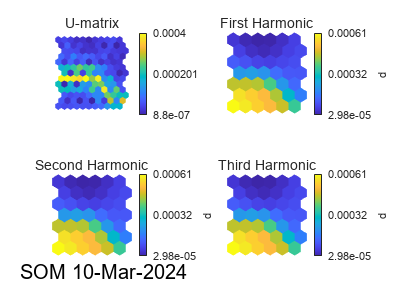


%% Calculate pairwise distances between all neurons in the SOM for later use
neuron_distances = pdist2(sMap.codebook, sMap.codebook);

%% Automatic labeling of the SOM
sMap = som_autolabel(sMap, sD, 'vote'); % Using 'vote' method for automatic labeling

%% Assign labels to unlabeled neurons based on nearest labeled neighbor
for i = 1:size(sMap.codebook, 1)
    if isempty(sMap.labels{i, 1}) % Check if the neuron is unlabeled
        labeledNeighbors = findLabeledNeighbors(i, sMap, neuron_distances);
        if ~isempty(labeledNeighbors)
            sMap.labels{i, 1} = labeledNeighbors{1}; % Assign the label of the nearest labeled neighbor
        end
    end
end

%% Basic visualization of the trained SOM
som_show(sMap);

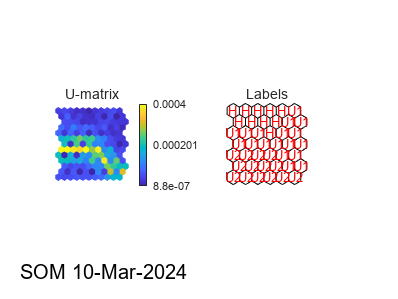


%% U-matrix visualization with labels
figure;
som_show(sMap, 'umat', 'all', 'empty', 'Labels');
som_show_add('label', sMap, 'Textsize', 8, 'TextColor', 'r', 'Subplot', 2);


%% Testing with SOM - Process Similar to Training Data
% Load and process test data - similar structure as training phase
all_data_testing = loadDataFromFolder(folder_path_testing);
features_testing = extractFeatures(all_data_testing);

% Find Best Matching Units for test data
bmus = som_bmus(sMap, features_testing);

%% Display Testing Results
predicted_labels = cell(length(bmus), 1);
for i = 1:length(bmus)
    predicted_labels{i} = sMap.labels{bmus(i),1}; % Updated to use labels from sMap
end

disp(predicted_labels);

    {'H' }
    {'H' }
    {'H' }
    {'H' }
    {'H' }
    {'H' }
    {'H' }
    {'H' }
    {'H' }
    {'H' }
    {'H' }
    {'U1'}
    {'U1'}
    {'U1'}
    {'U1'}
    {'U1'}
    {'U1'}
    {'U1'}
    {'U1'}
    {'U1'}
    {'U2'}
    {'U2'}
    {'U2'}
    {'U2'}
    {'U2'}
    {'U2'}
    {'U2'}
    {'U2'}
    {'U2'}
    {'U2'}




% Define actual labels for the test data
actual_labels = [repmat({'H'}, 10, 1); 
                 repmat({'U1'}, 10, 1);
                 repmat({'U2'}, 10, 1)];

% Compare predicted labels with actual labels and calculate accuracy
correct_predictions = 0;
for i = 1:length(predicted_labels)
    if strcmp(predicted_labels{i}, actual_labels{i})
        correct_predictions = correct_predictions + 1;
    end
end

% Calculate the accuracy
accuracy = correct_predictions / length(predicted_labels);
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 96.67%


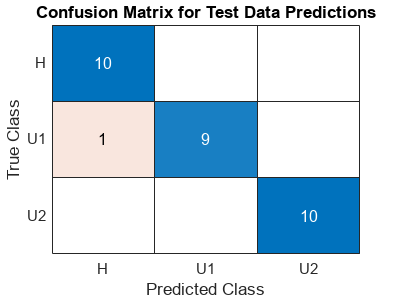


%% Generate Confusion Matrix
% Convert cell arrays of labels to categorical for confusion matrix computation
actual_cats = categorical(actual_labels);
predicted_cats = categorical(predicted_labels);

% Generate the confusion matrix
[C, order] = confusionmat(actual_cats, predicted_cats);

% Ensure 'order' is a cell array of strings (for compatibility with all MATLAB versions)
orderStr = cellstr(order); % Convert categorical array to cell array of strings

% Visualize the confusion matrix
figure;
confusionchart(C, orderStr);
title('Confusion Matrix for Test Data Predictions');

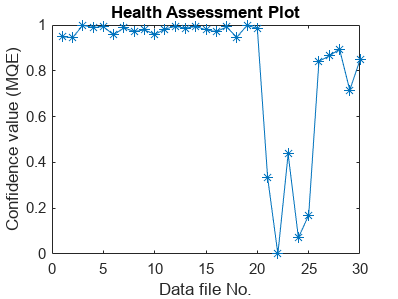


%% Calculate the MQE values for the testing data set
numTestSamples = size(features_testing, 1); % Number of testing samples
MQEt = zeros(numTestSamples, 1); % Preallocate array for MQE values

for ii = 1:numTestSamples
    % Extract single test sample
    singleTestData = features_testing(ii, :);
    
    % Find BMU for the test sample
    bmu_index = som_bmus(sMap, singleTestData);
    bmu_vector = sMap.codebook(bmu_index, :); % Extract the BMU codebook vector
    
    % Calculate MQE value for each sample
    MQEt(ii) = norm(singleTestData - bmu_vector); % Euclidean distance
end

% Normalize MQE
MQEtn = 1 - (MQEt / max(MQEt)); % Normalize MQE

%% Plot the calculated MQE values 
% Observe the difference between normal condition and faulty conditions
figure; % Create a new figure window
plot(MQEtn, '-*');
xlabel('Data file No.');
ylabel('Confidence value (MQE)');
title('Health Assessment Plot');


% Supporting Functions


function [all_data] = loadDataFromFolder(folder_path)
    file_list = dir(fullfile(folder_path, '*.txt'));
    all_data = cell(length(file_list), 1);
    for i = 1:length(file_list)
        file_path = fullfile(folder_path, file_list(i).name);
        all_data{i} = importdata(file_path);
    end
    return;
end

function features = extractFeatures(all_data)
    num_samples = length(all_data);
    features = zeros(num_samples, 3); % Assuming three features for simplicity
    for i = 1:num_samples
        data = all_data{i}.data;
        features(i, :) = calculateHarmonics(data);
    end
    return;
end

function [firstHarmonic, secondHarmonic, thirdHarmonic] = calculateHarmonics(data)
    Fs = 2560; % Sampling frequency
    Y = fft(data);
    N = length(data);
    P2 = abs(Y/N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(N/2))/N;
    harmonicFrequencies = [20, 40, 60]; % Example harmonic frequencies
    harmonics = zeros(1, length(harmonicFrequencies));
    for h = 1:length(harmonicFrequencies)
        [~, index] = min(abs(f - harmonicFrequencies(h)));
        harmonics(h) = P1(index);
    end
    firstHarmonic = harmonics(1);
    secondHarmonic = harmonics(2);
    thirdHarmonic = harmonics(3);
    return;
end

function labels = findLabeledNeighbors(index, sMap, neuron_distances)
    dists = neuron_distances(index, :);
    [~, sortedIndices] = sort(dists, 'ascend');
    labels = {};
    for j = sortedIndices
        if ~isempty(sMap.labels{j, 1})
            labels{end+1} = sMap.labels{j, 1};
        end
        if length(labels) >= 1 % Can adjust how many labeled neighbors to consider
            break;
        end
    end
    return;
end
